# Model building for my mémoir

## Daudi's model

**System setup**

clear all
close all
clc

**Variables**

x0 = 500;
y0 = 0;
z0 = [15, 30, 45 60];
w0 = 0;
ta = 10;

**Parameters**

Coefficients

an = 0.000154;  % $\alpha$ caterpillar attack rate
l = 0.015;%0;%.001;%0.015;      % $\lambda$ maize death due to caterpillar attaque
d = 0.071;      % $\delta$ caterpillar to adult rate
g = 0.071;      % $\gamma$ egg to caterpillar
rh = 0.0417;%0.1,0.0417;    % $\rho$ fecondity rate
e = 1.6; %0.1;%1.6       % $e$ biomass conversion to caterpillar
k = x0/2;
coef = [an, l, d, g, rh, e, k];

Mortality rates

uy = 0.0071;    % $\mu_y$ mortality rate of caterpillar
uz = 0.115;     % $\mu_z$ motality rate of adult
uw = 0.04;      % $\mu_w$ motality rate of egg
drate = [uy, uz, uw];

**Time**

t0 = 0;
t1 = 63;
T = 160;
I = [t0 T];
fig = 0;

## **My model**

**System setup**

% clear all
% close all
% clc

**Variables**

%x0 = 500;
%y0 = 0;
%z0 = [15, 30, 45, 60];
%w0 = 0;

**Parameters**

Coefficients

%an = 0;%.0002;%0.000154;  % $\alpha$ caterpillar attack rate
%l = 0.01;%.015;      % $\lambda$ maize death due to caterpillar attaque
%d = 0.071;      % $\delta$ caterpillar to adult rate
%g = 0.1;%0.071;      % $\gamma$ egg to caterpillar
%rh = 0.07;%0.0417;    % $\rho$ fecondity rate
%e = 1.6;        % $e$ caterpillar grow due to maize consumption
%k = x0/2;
rr = 0.01;
coef = [an, l, d, g, rh, e, k, rr];

Mortality rates

% uy = 0.0071;    % $\mu_y$ mortality rate of caterpillar
% uz = 0.05;  %0.115;     % $\mu_z$ motality rate of adult
% uw = 0.04;      % $\mu_w$ motality rate of egg
% drate = [uy, uz, uw];

**Time**

% t0 = 0;
% t1 = 63;
% T = 160;
% I = [t0 T];

**Resolution**


% tit = ["maize", "caterpillar", "adult", "egg"];
% for i = 1:length(z0)
%     s0 = [x0, y0, z0(i), w0];
%     [t,s] = myMod(s0, coef, drate, I);
%     for j = 1:4
%         figure(j+fig)
%         hold on
%         %subplot(2,2,j)
%         plot(t,s(:,j))
%         title(tit(j))
%         grid minor
%     end
% end
% fig = fig + j;

## **My model SIS's version 7**

**System setup**

% clear all
% close all
% clc
 

**Variables**

x0 = 300;
% x00 = 0;
% xd = 0;
% y0 = 0;
%z0 = [1, 30, 45, 60];
% w0 = 0;

**Parameters**

Coefficients

ta = [3 8.5];
an = 1/10;%0.00154*3;  % $\alpha$ caterpillar attack rate
l = 1/21;%0.015;%0.015;%0.0115;      % $\lambda$ maize death due to caterpillar attaque
d = 1/7;%0.071;      % $\delta$ caterpillar to adult rate
g = 1/5;%1/4t(1);%0.071;      % $\gamma$ egg to caterpillar
rh = 0.5;%0.417;    % $\rho$ fecondity rate
% e = 0.01;%1.6;        % $e$ caterpillar grow due to maize consumption
k = x0;
rr = 1/10 ;
z0 = 0;
x00 = [15, 30, 45, 60];
coef = [an, l, d, g, rh, e, k, rr];

Mortality rates

uy = 1/ta(2);    % $\mu_y$ mortality rate of caterpillar
uz = 0.3;%1/17.5;  %0.115;     % $\mu_z$ motality rate of adult
uw = 1/ta(1);      % $\mu_w$ motality rate of egg
drate = [uy, uz, uw];

**Time**

t0 = 10;
% t1 = 63;
T = 160;
I = [0 T];

**Resolution**

% %s0 = [x0-, 0, x0, y0, z0, w0];
% tit = ["maize_S", "maize_I","maize", "caterpillar", "adult", "egg"];
% S = 0;
% for i = 1:length(sig)
%     s0 = [x0, 0, x0, y0, sig/uz, w0];
%     [t,s] = myModSIS_7(s0, coef, drate, ta, t0, sig, I);
% %     if i == 1
% %         S = s;
% %     else
% %         S = [S;s];
% %     end
%     for j = 1:6
%         figure(j+fig)
%         hold on
%         %subplot(2,2,j)
%         plot(t,s(j,:))
%         title(tit(j))
%         grid minor
%     end
% end
% fig = fig + j;
% %figure()
% %n=6
% %plot(t,[S(1,:)+S(2,:); S(n+1,:)+S(n+2,:); S(2*n+1,:)+S(2*n+2,:); S(3*n+1,:)+S(3*n+2,:)])
% %plot(t,[S(1,:)+S(2,:); S(n+1,:)+S(n+2,:); S(2*n+1,:)+S(2*n+2,:); S(3*n+1,:)+S(3*n+2,:)])
% %s(1,end-100) + s(2,end-100)
% %d*rh*.


## **My model SIS's version**

**System setup**

% clear all
% close all
% clc
 

**Variables**

%x0 = 300;
x00 = 0;
xd = 0;
y0 = 0;
z0 = [1, 30, 45, 60];
w0 = 0;

**Parameters**

Coefficients

%an = 0.00154*3;%7;  % $\alpha$ caterpillar attack rate
%l = 0.015;%0.015;%0.015;%0.0115;      % $\lambda$ maize death due to caterpillar attaque
%d = 0;%.071;      % $\delta$ caterpillar to adult rate
% g = 0.071;      % $\gamma$ egg to caterpillar
%rh = 0.1*4;%0.417;    % $\rho$ fecondity rate
%e = 0.01*10;%2;%1.6;        % $e$ caterpillar grow due to maize consumption
% k = 0;%x0/2;
%rr = 0.01;
coef = [an, l, d, g, rh, e, k, rr];

Mortality rates

% uy = 0.0071;    % $\mu_y$ mortality rate of caterpillar
% uz = 0.05;  %0.115;     % $\mu_z$ motality rate of adult
% uw = 0.4;      % $\mu_w$ motality rate of egg
% drate = [uy, uz, uw];

**Time**

% t0 = 0;
% t1 = 63;
% T = 160;
I = [0 T];

**Resolution**

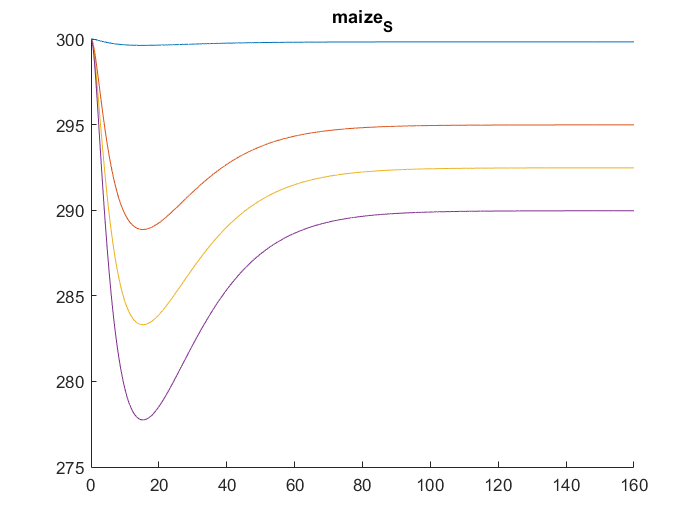

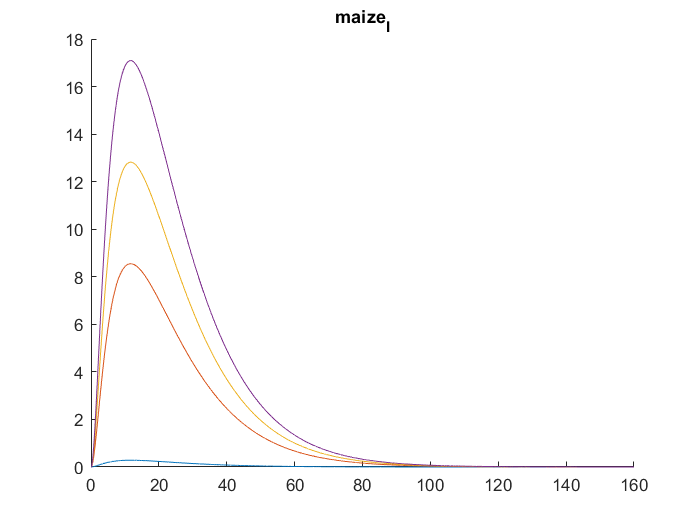

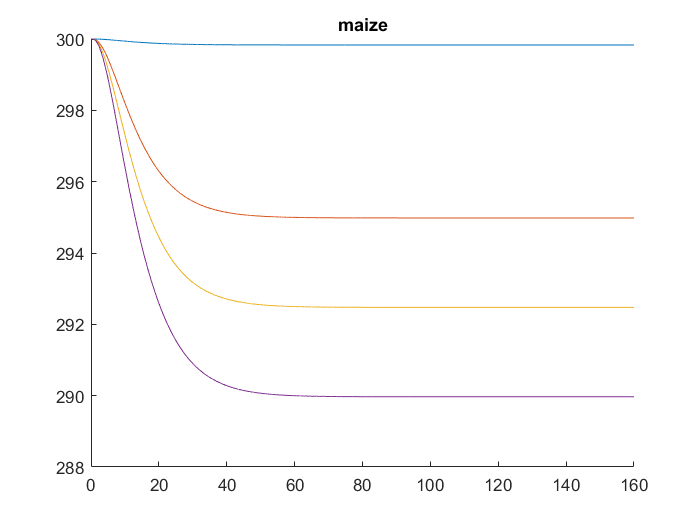

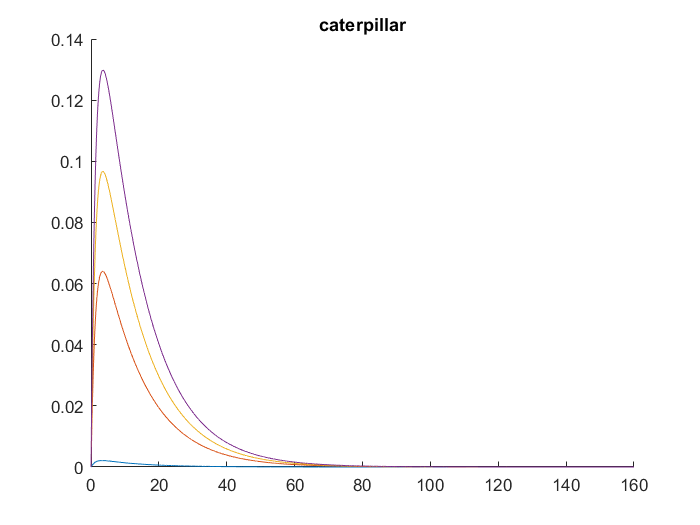

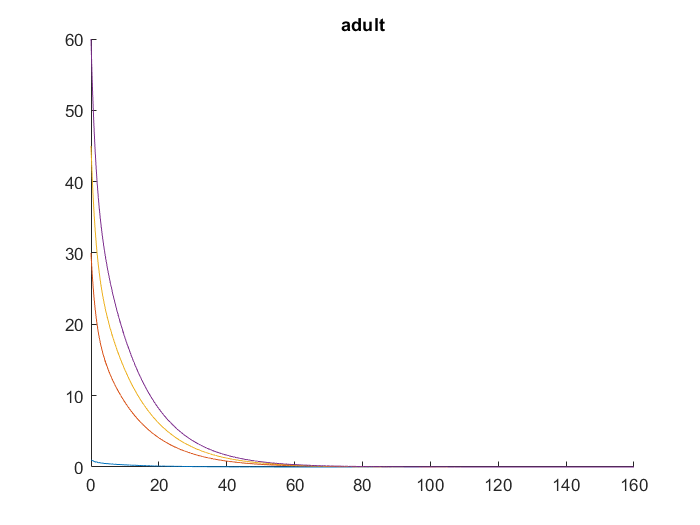

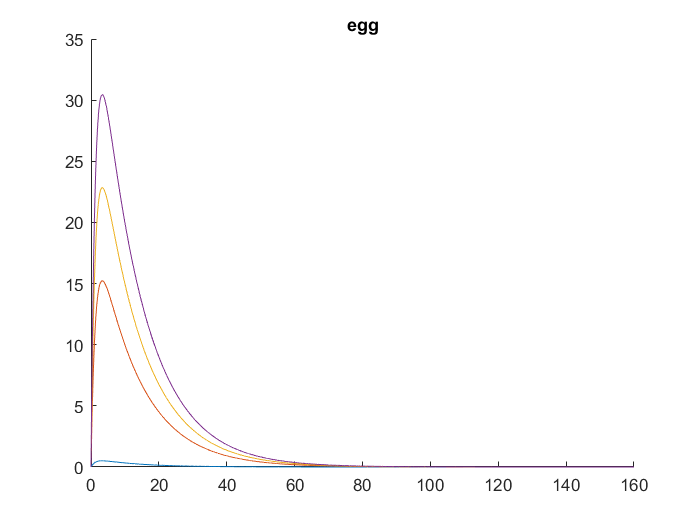


tit = ["maize_S", "maize_I","maize", "caterpillar", "adult", "egg"];
S = 0;
for i = 1:length(z0)
    s0 = [x0, x00, x0, y0, z0(i), w0];
    [t,s] = myModSIS_2(s0, coef, drate, I);
    if i == 1
        S = s;
    else
        S = [S;s];
    end
    for j = 1:6
        figure(j+fig)
        hold on
        %subplot(2,2,j)
        plot(t,s(:,j))
        title(tit(j))
        grid minor
    end
end

% figure()
% n=6
%     plot(t,[S(1,:)+S(2,:); S(n+1,:)+S(n+2,:); S(2*n+1,:)+S(2*n+2,:); S(3*n+1,:)+S(3*n+2,:)])
fig = fig + j;
% s(1,end-100) + s(2,end-100)
% dexp = @(l,t) l*exp(-l*t);
% Fexp = @(l,t) 1 - exp(-l*t);
% sexp = @(l,t) exp(-l*t);
% figure()
% a=0.05;
% plot(t, [dexp(a,t); dexp(a/2,t)])
% figure()
% plot(t, [Fexp(a,t); sexp(a,t); sexp(a/2,t)])

## **My model SIS's version**

**System setup**

% clear all
% close all
% clc
 

**Variables**

% x0 = 300;
% x00 = 0;
% xd = 0;
% y0 = 0;
% z0 = [15, 30, 45, 60];
% w0 = 0;

**Parameters**

Coefficients

% an = 0.00154*3;  % $\alpha$ caterpillar attack rate
% l = 0.01;%0.015;%0.015;%0.0115;      % $\lambda$ maize death due to caterpillar attaque
% d = 0.071;      % $\delta$ caterpillar to adult rate
% g = 0.071;      % $\gamma$ egg to caterpillar
% rh = 0.1*2;%0.417;    % $\rho$ fecondity rate
% e = 0.01;%1.6;        % $e$ caterpillar grow due to maize consumption
% k = 0;%x0/2;
% rr = 0.001 ;
% coef = [an, l, d, g, rh, e, k, rr];

Mortality rates

% uy = 0.0071;    % $\mu_y$ mortality rate of caterpillar
% uz = 0.05;  %0.115;     % $\mu_z$ motality rate of adult
% uw = 0.4;      % $\mu_w$ motality rate of egg
% drate = [uy, uz, uw];

**Time**

% t0 = 0;
% t1 = 63;
% T = 160;
% I = [t0 T];

**Resolution**


tit = ["maize_S", "maize_I","maize_D", "caterpillar", "adult", "egg"];
S = 0;
for i = 1:length(z0)
    s0 = [x0, x00, xd, y0, z0(i), w0];
    [t,s] = myModSIS_3(s0, coef, drate, I);
    if i == 1
        S = s;
    else
        S = [S;s];
    end
    for j = 1:6
        figure(j+fig)
        hold on
        %subplot(2,2,j)
        plot(t,s(j,:))
        title(tit(j))
        grid minor
    end
end

Undefined function or variable 'Rung_Kutta4'.

Error in myModSIS_3 (line 37)
[t,s] = Rung_Kutta4(myfSIS, s0, I, I(end)*N);

figure()
n=6
    plot(t,[S(1,:)+S(2,:); S(n+1,:)+S(n+2,:); S(2*n+1,:)+S(2*n+2,:); S(3*n+1,:)+S(3*n+2,:)])
s(1,end-100) + s(2,end-100)
fig = fig + j+1;

## **My model SIS's version**

**System setup**

% clear all
% close all
% clc
 

**Variables**

% x0 = 300;
% x00 = 0;
% xd = 0;
% y0 = 0;
% z0 = [15, 30, 45, 60];
% w0 = 0;

**Parameters**

Coefficients

an = 0.2;%0.00154*3;  % $\alpha$ caterpillar attack rate
% l = 0.01;%0.015;%0.015;%0.0115;      % $\lambda$ maize death due to caterpillar attaque
% d = 0.071;      % $\delta$ caterpillar to adult rate
% g = 0.071;      % $\gamma$ egg to caterpillar
% rh = 0.1*2;%0.417;    % $\rho$ fecondity rate
% e = 0.01;%1.6;        % $e$ caterpillar grow due to maize consumption
% k = 0;%x0/2;
rr = 0.001 ;
% coef = [an, l, d, g, rh, e, k, rr];

Mortality rates

% uy = 0.0071;    % $\mu_y$ mortality rate of caterpillar
% uz = 0.05;  %0.115;     % $\mu_z$ motality rate of adult
% uw = 0.4;      % $\mu_w$ motality rate of egg
% drate = [uy, uz, uw];

**Time**

% t0 = 0;
% t1 = 63;
% T = 160;
% I = [t0 T];

**Resolution**


tit = ["maize_S", "maize_I","maize_D", "caterpillar", "adult", "egg"];
S = 0;
for i = 1:length(z0)
    s0 = [x0, x00, xd, y0, z0(i), w0];
    [t,s] = myModSIS_4(s0, coef, drate, I);
    if i == 1
        S = s;
    else
        S = [S;s];
    end
    for j = 1:6
        figure(j+fig)
        hold on
        %subplot(2,2,j)
        plot(t,s(j,:))
        title(tit(j))
        grid minor
    end
end
fig = fig + j;
figure()
n=6
plot(t,[S(1,:)+S(2,:); S(n+1,:)+S(n+2,:); S(2*n+1,:)+S(2*n+2,:); S(3*n+1,:)+S(3*n+2,:)])
s(1,end-100) + s(2,end-100)

## **My model SIS's version 6**

**System setup**

% clear all
% close all
% clc
 

**Variables**

x0 = 300;
% x00 = 0;
% xd = 0;
% y0 = 0;
%z0 = [1, 30, 45, 60];
% w0 = 0;

**Parameters**

Coefficients

ta = [2 8];
an = 1/10;%0.00154*3;  % $\alpha$ caterpillar attack rate
l = 1/21;%0.015;%0.015;%0.0115;      % $\lambda$ maize death due to caterpillar attaque
d = 1/7;%0.071;      % $\delta$ caterpillar to adult rate
g = 1/5;%1/4t(1);%0.071;      % $\gamma$ egg to caterpillar
rh = 0.5;%0.417;    % $\rho$ fecondity rate
% e = 0.01;%1.6;        % $e$ caterpillar grow due to maize consumption
k = 0;
rr = 1/10 ;
z0 = 0;
sig = [1, 30, 45, 60];
coef = [an, l, d, g, rh, e, k, rr];

Mortality rates

uy = 1/ta(2);    % $\mu_y$ mortality rate of caterpillar
uz = 0.3;%1/17.5;  %0.115;     % $\mu_z$ motality rate of adult
uw = 1/ta(1);      % $\mu_w$ motality rate of egg
drate = [uy, uz, uw];

**Time**

t0 = 10;
% t1 = 63;
T = 160;
I = [0 T];

**Resolution**

s0 = [x0, 0, x0, y0, z0, w0];
tit = ["maize_S", "maize_I","maize_D", "caterpillar", "adult", "egg"];
S = 0;
for i = 1:length(sig)
    %s0 = [x0, x00, x0, y0, z0(i), w0];
    [t,s] = myModSIS_6(s0, coef, drate, ta, t0, sig(i), I);
%     if i == 1
%         S = s;
%     else
%         S = [S;s];
%     end
    for j = 1:6
        figure(j+fig)
        hold on
        %subplot(2,2,j)
        plot(t,s(j,:))
        title(tit(j))
        grid minor
    end
end
fig = fig + j;
%figure()
%n=6
%plot(t,[S(1,:)+S(2,:); S(n+1,:)+S(n+2,:); S(2*n+1,:)+S(2*n+2,:); S(3*n+1,:)+S(3*n+2,:)])
%plot(t,[S(1,:)+S(2,:); S(n+1,:)+S(n+2,:); S(2*n+1,:)+S(2*n+2,:); S(3*n+1,:)+S(3*n+2,:)])
%s(1,end-100) + s(2,end-100)
%d*rh*

## **My model SIS's version 8**

**System setup**

% clear all
% close all
% clc
 

**Variables**

x0 = 300;
% x00 = 0;
% xd = 0;
% y0 = 0;
%z0 = [1, 30, 45, 60];
% w0 = 0;

**Parameters**

Coefficients

ta = [3 8.5];
an = 1/10;%0.00154*3;  % $\alpha$ caterpillar attack rate
l = 1/21;%0.015;%0.015;%0.0115;      % $\lambda$ maize death due to caterpillar attaque
d = 1/7;%0.071;      % $\delta$ caterpillar to adult rate
g = 1/5;%1/4t(1);%0.071;      % $\gamma$ egg to caterpillar
rh = 0.5;%0.417;    % $\rho$ fecondity rate
% e = 0.01;%1.6;        % $e$ caterpillar grow due to maize consumption
k = x0;
rr = 1/10 ;
z0 = 0;
x00 = [15, 30, 45, 60];
coef = [an, l, d, g, rh, e, k, rr];

Mortality rates

uy = 1/ta(2);    % $\mu_y$ mortality rate of caterpillar
uz = 0.3;%1/17.5;  %0.115;     % $\mu_z$ motality rate of adult
uw = 1/ta(1);      % $\mu_w$ motality rate of egg
drate = [uy, uz, uw];

**Time**

t0 = 10;
% t1 = 63;
T = 160;
I = [0 T];

**Resolution**

%s0 = [x0-, 0, x0, y0, z0, w0];
tit = ["maize_S", "maize_I","maize", "caterpillar", "adult", "egg"];
S = 0;
for i = 1:length(sig)
    s0 = [x0-x00(i), x00(i), x0, y0, z0, w0];
    [t,s] = myModSIS_7(s0, coef, drate, ta, t0, 0, I);
%     if i == 1
%         S = s;
%     else
%         S = [S;s];
%     end
    for j = 1:6
        figure(j+fig)
        hold on
        %subplot(2,2,j)
        plot(t,s(j,:))
        title(tit(j))
        grid minor
    end
end
fig = fig + j;
%figure()
%n=6
%plot(t,[S(1,:)+S(2,:); S(n+1,:)+S(n+2,:); S(2*n+1,:)+S(2*n+2,:); S(3*n+1,:)+S(3*n+2,:)])
%plot(t,[S(1,:)+S(2,:); S(n+1,:)+S(n+2,:); S(2*n+1,:)+S(2*n+2,:); S(3*n+1,:)+S(3*n+2,:)])
%s(1,end-100) + s(2,end-100)
%d*rh*

## **My model SIS's version 7**

**System setup**

% clear all
% close all
% clc
 

**Variables**

x0 = 300;
% x00 = 0;
% xd = 0;
% y0 = 0;
%z0 = [1, 30, 45, 60];
% w0 = 0;

**Parameters**

Coefficients

ta = [3 8.5];
an = 1/10;%0.00154*3;  % $\alpha$ caterpillar attack rate
l = 1/21;%0.015;%0.015;%0.0115;      % $\lambda$ maize death due to caterpillar attaque
d = 1/7;%0.071;      % $\delta$ caterpillar to adult rate
g = 1/5;%1/4t(1);%0.071;      % $\gamma$ egg to caterpillar
rh = 0.5;%0.417;    % $\rho$ fecondity rate
% e = 0.01;%1.6;        % $e$ caterpillar grow due to maize consumption
k = x0;
rr = 1/10 ;
z0 = 0;
x00 = [15, 30, 45, 60];
coef = [an, l, d, g, rh, e, k, rr];

Mortality rates

uy = 1/ta(2);    % $\mu_y$ mortality rate of caterpillar
uz = 0.3;%1/17.5;  %0.115;     % $\mu_z$ motality rate of adult
uw = 1/ta(1);      % $\mu_w$ motality rate of egg
drate = [uy, uz, uw];

**Time**

t0 = 10;
% t1 = 63;
T = 160;
I = [0 T];

**Resolution**

% %s0 = [x0-, 0, x0, y0, z0, w0];
% tit = ["maize_S", "maize_I","maize", "caterpillar", "adult", "egg"];
% S = 0;
% for i = 1:length(sig)
%     s0 = [x0, 0, x0, y0, sig/uz, w0];
%     [t,s] = myModSIS_7(s0, coef, drate, ta, t0, sig, I);
% %     if i == 1
% %         S = s;
% %     else
% %         S = [S;s];
% %     end
%     for j = 1:6
%         figure(j+fig)
%         hold on
%         %subplot(2,2,j)
%         plot(t,s(j,:))
%         title(tit(j))
%         grid minor
%     end
% end
% fig = fig + j;
% %figure()
% %n=6
% %plot(t,[S(1,:)+S(2,:); S(n+1,:)+S(n+2,:); S(2*n+1,:)+S(2*n+2,:); S(3*n+1,:)+S(3*n+2,:)])
% %plot(t,[S(1,:)+S(2,:); S(n+1,:)+S(n+2,:); S(2*n+1,:)+S(2*n+2,:); S(3*n+1,:)+S(3*n+2,:)])
% %s(1,end-100) + s(2,end-100)
% %d*rh*

## Daudi's model

**System setup**

clear all
close all
clc

**Variables**

x0 = 1000;
y0 = 0;
z0 = [1, 30, 45 60];
w0 = 0;
ta = 10;

**Parameters**

Coefficients

an = 0.000154;  % $\alpha$ caterpillar attack rate
l = 0.015;%0;%.001;%0.015;      % $\lambda$ maize death due to caterpillar attaque
d = 0.071;      % $\delta$ caterpillar to adult rate
g = 0.071;      % $\gamma$ egg to caterpillar
rh = 0.0417;%0.1,0.0417;    % $\rho$ fecondity rate
e = 1.6; %0.1;%1.6       % $e$ caterpillar grow due to maize consumption
k = x0 ;
%coef = [an, l, d, g, rh, e, k];

Mortality rates

uy = 0.0071;    % $\mu_y$ mortality rate of caterpillar
uz = 0.115;     % $\mu_z$ motality rate of adult
uw = 0.04;      % $\mu_w$ motality rate of egg
drate = [uy, uz, uw];

%e = (d+uy)/(an*k);
coef = [an, l, d, g, rh, e, k];

**Time**

t0 = 0;
t1 = 63;
T = 160;%105;
I = [t0 T];

**Resolution**

fig = 0;
tit = ["maize_s", "maize_i", "maize", "caterpillar", "adult", "egg"];
for i = 1:length(z0)
    s0 = [x0, 0, x0, y0, z0(i), w0];
    %[t,s] = daudiMod(s0, coef, drate, I);
    [t,s] = daudiMod2(s0, coef, drate, I);
    for j = 1:6
        figure(fig+j)
        hold on
        %subplot(2,2,j)
        plot(t,s(j,:))
        title(tit(j))
        grid minor
    end
end
% figure(1)
% hold on
% plot(t, x0 * exp(-l*t))
fig = fig + j;%+1;